# Computing path vectors and minimal cut sets

## Author: Susan Ghaderi, Luxembourg Centere for Systems Biomedicine 

## Reviewers: Sylvain Arreckx, Laurent Heirendt

## INTRODUCTION

During this tutorial, you will learn how to compute elementary (flux) modes / elementary (flux) vectors and a minimal generating set (convex basis) of flux cones or flux polyhedra associated with mass-flow networks [2] and how to compute computes cutsets for paths/cycles/elementary modes with Berge algorithm [1].

 To compute elementary modes and convex bases, two different scenarios can be considered: homogeneous and inhomogeneous constraints cases.

-  In homogeneous constraints case, elementary modes are flux vectors with minimal support of the polyhedral cone defined by the steady state assumptions and reversibility constraints. Also, a convex basis is a minimal set of vectors sufficient to generate all flux vectors within the flux cone by non-negative linear combinations of convex basis vectors, which are always a subset of the elementary modes.

- In the other hand in inhomogeneous constraints, elementary modes are a generalization of elementary modes which are all extreme rays, extreme points and representatives of all support-minimal flux patterns or only a minimal set of unbounded (basis of lineality space + extreme rays) and bounded (extreme points) generators spanning the resulting general flux polyhedron [3].

Elementary modes describe a feasible and balanced (steady state) flux distribution through the network, which is minimal with respect to utilized reactions (enzymes). The condition of being ‘minimal’ (elementary, non-decomposable, irreducible) is fundamental and means that removing any reaction in an elementary mode impedes the realization of a non-zero steady-state flux distribution (and therefore of a functionality) by means of the remaining reactions of the elementary mode. Now, assume that we want to prevent the production of metabolite X.  One strategy would be to inactivate (cut) one or several reactions in the network, e.g. by deleting the genes of certain enzymes or by other manipulations resulting in an inhibition of enzyme activity. This leads us to the definition of a cut set: a set of reactions a cut set (with respect to a defined objective reaction) if after the removal of these reactions from the network no feasible balanced flux

We present two algorithms which enable the computation of the elementary modes/extreme pathways in each network related to user-defined objective models and reactions.

## MATERIALS

- *Please ensure that the COBRA Toolbox has been properly installed and initialised. *

- *Also, you should install CNA (CellNetAnalyzer) software and initialise it. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

*Before you start with these codes, you should initialise The COBRA Toolbox and CNA software by the following commands*

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

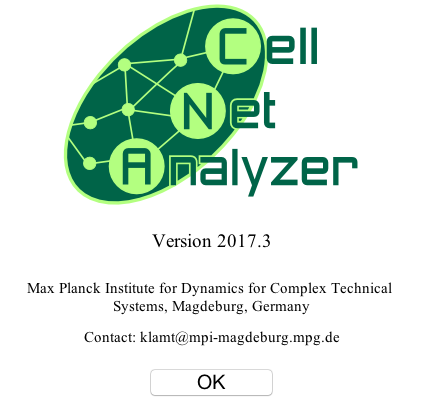

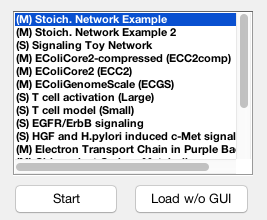

% Add path to Cell Net Analyzer
CNAPath = '~/CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna

## Elementary modes and extreme pathways

The mandatory inputs for computing elementary modes and extreme pathways are a model that user are going to compute its path vectors (elementary modes or extreme pathways (convex basis)) and a directory that CNA model is going to be saved there. A model should be a COBRA model, a simple MATLAB `struct` with fields defined in the [Documentation](https://opencobra.github.io/cobratoolbox/docs/COBRAModelFields.html). 

% define the model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'pathVectorsAndMinimalCutSets'])
load('smallmodel.mat')
% define the directory (the place that CNA model will % be saved there)
directory = 'Pathwaysvector';
output = pathVectors(smallmodel, directory)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

Can't load log handler "ch.javasoft.util.logging.StandardOutHandler"
java.lang.ClassNotFoundException: ch.javasoft.util.logging.StandardOutHandler
java.lang.ClassNotFoundException: ch.javasoft.util.logging.StandardOutHandler
	at java.net.URLClassLoader$1.run(URLClassLoader.java:366)
	at java.net.URLClassLoader$1.run(URLClassLoader.java:355)
	at java.security.AccessController.doPrivileged(Native Method)
	at java.net.URLClassLoader.findClass(URLClassLoader.java:354)
	at java.lang.ClassLoader.loadClass(ClassLoader.java:425)
	at sun.misc.Launcher$AppClassLoader.loadClass(Launcher.java:308)
	at java.lang.ClassLoader.loadClass(ClassLoader.java:358)
	at java.util.logging.LogManager$4.run(LogManager.java:808)
	at java.security.AccessController.doPrivileged(Native Method)
	at java.util.logging.LogManager.loadLoggerHandlers(LogManager.java:802)
	at java.util.logging.LogManager.initializeGlobalHandlers(LogManager.java:1406)
	at java.util.logging.LogManager.access$1500(LogManager.java:148)
	at jav

 
Final number of elementary modes: 2
 
Removing 0 external metabolites


output =       efm: [2×5 double]
      rev: [2×1 double]
      idx: [2 3 4 5 6]
      ray: [1 1]
    model: [1×1 struct]


## Optional inputs

The function can have some optional inputs which depend on computing elementary modes or extreme pathways. We explain the most important optional inputs in the following. 

- `constraints`: is a matrix specifying homogeneous `0` and inhomogeneous `1` constraints on the reaction rates; 

- `mexVe``rsion`: there are four options for mexversion, that the default value is `4`.

                       - `1`:  use CNA mex files,

                       - `2`: use Metatool mex files,

                       - `3`: use both CNA and Metatool mex files  

                       - `4`: use Marco Terzer's EFM tool (see http://www.csb.ethz.ch/tools/index)

- `irrevFlag` : if set to `0,` considers the reversibility of reactions and set to `1` if it does not consider reversibility.

- `convbasisFlag`: if set to `0`, all elementary modes/vectors are caculated and if set to `1`, only a minimal generating set (convex basis) is calculated (default: `0`).

- `isoFlag` : consider isoenzymes (parallel reactions) only once or not; the default value is (default: `0`).

- `cMacro`: vector containing the concentrations (g/gDW) of the macromolecules if a variable biomass composition has been defined (cnap.mue not empty). Can be empty when cnap.mue or cnap.macroComposition is empty. If it is empty and cnap.mue is not empty then cnap.macroDefault is used. In CNA models default is cnap.macroDefault, but in COBRA models if it is not contain mu (biomass composition) then the default value is empty.

- `display`: control the detail of console output; the default value is '`None`'. Other options are `'Iteration'`, `'All'` or `'Details'`.

- `positivity`: whether a non-negative convex basis  `1` or not `0`. If yes it converts every reversible reaction to two irreversible reactions. 

For a complete list of optional inputs and their definition, you can run the following command.

help pathVectors

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  This code can be used to compute elementary mode and extreme pathway 
  (convex basis) of an arbitrary COBRA model by the CNA software 
  package.
 
  INPUT           :
  model           :    COBRA model
  directory       :    A path that CNA model is going to be saved there
  constraints     :    empty 
                       cnap.numr
                       many rows and up to 4 columns:
                    -  COLUMN1 specifies excluded/enforced reactions: if
                       (constraints(i,1)==0) then onlythose modes / rays 
                       / points will be computed that do not include 
                       reaction i; constraints(i,1)~=0 and
                       constraints(i)~=NaN enforces reaction i, i.e. only  
                       those modes / rays / points will be computed that
                       involve reaction i; for all other reactions choose
                       constraint(

The following function compute a convex basis for the model by the name smallmodel which its CNA version will be saved in the `directory` address.

output = pathVectors(smallmodel, directory,'convBasisFlag',1)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

 
 
Final number of convex basis vectors: 2
 
Removing 0 external metabolites


output =       efm: [2×5 double]
      rev: [1 1]
      idx: [2 3 4 5 6]
      ray: [1 1]
    model: [1×1 struct]


## Output

The output of `phatVectors.m is`

-  `output.efm `:  the matrix that contains (row-wise) the elementary modes (or elementary vectors) or a minimal set of generators (lineality space + extreme rays/points), depending on the chosen scenario. The columns  correspond to the reactions; the column indices of efms (with respect to the columns in cnap.stoichMat) are stored in the returned  variable idx (see below; note that columns are removed in efms if the corresponding reactions are not contained in any mode)

-  `output.rev`  :    vector indicating for each mode whether it is reversible(0)/irreversible (1)

-  `output.idx `:    maps the columns in efm onto the column indices in cnap.stoichmat, i.e. idx(i) refers to the column number in cnap.stoichmat (and to the row number in cnap.reacID)

- `output.ray `:    indicates whether the i-th row (vector) in efm is an unbounded (1) or bounded (0) direction of the flux cone / flux polyhedron. Bounded directions (such as extreme points) can only arise if an inhomogeneous problem was defined.

To clarify above description for example, if you look at the output `output.efm` is 

output.efm

ans =     -1     1     0     0    -1
     0     0     1    -1    -1


and 

output.idx

ans =      2     3     4     5     6


That means reactions 2, 3, 4 ,5 and 6 participate in the elementary modes. For example, reactions 2, 3 and 6 are made elementary mode one in `output.efm(1), `which in every elementary mode two of reaction use reversible reactions.

To understand the meaning of all of the output you can type `help pathVectors`

## Computing minimal cut set

The mandatory input in minimal cut set code is the set such as paths/cycles/elementary modes that you are going to compute its minimal cut set.

output = minimalCutSets(output.efm)

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 0 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 1
 
2 equivalent elements found and removed
2 remaining elements
After 2 (of 2) iterations: 1 preliminary cut sets
 
Ready! Computation time: 0.07 sec
Longest list merge: 2.
Compressed MCS list length: 2.
 
Final result: 5 minimal cut sets
 


cutsets =      0     0     0     0     1
     1     0     1     0     0
     0     1     1     0     0
     1     0     0     1     0
     0     1     0     1     0


output =     cutsets: [5×5 double]


## TIMING

Running, the codes are dependent on the size of models may take long from 30 seconds to few hours. But in addition to the time of running you should consider between 60 seconds for start-up CNA software.

## ANTICIPATED RESULTS

If the user just wants to compute extreme pathways that all the elements be non-negative should use the following parameters

output = pathVectors(smallmodel, directory, 'convBasisFlag', 1, 'irrevFlag', 1, 'positivity', 1)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 10.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Sav

output =       efm: [6×10 double]
      rev: [1 1 1 1 1 1]
      idx: [1 2 3 4 5 6 7 8 9 10]
      ray: [1 1 1 1 1 1]
    model: [1×1 struct]


If the user wants to compute elementary modes, that is enough to just put `c``onvBa``sisFlag = 0,` and for checking other variables like reversibility and ... is optional.

output = pathVectors(smallmodel, directory, 'convBasisFlag', 0)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

output =       efm: [2×5 double]
      rev: [2×1 double]
      idx: [2 3 4 5 6]
      ray: [1 1]
    model: [1×1 struct]


## *TROUBLESHOOTING*

*To compute elementary modes, you should ****not ****use the *`mexVersion 2`*, because of this option just it is for computing convex basis.*

output = pathVectors(smallmodel, 'pathVectors', 'mexVersion', 2)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

Undefined function 'to_bits_c' for input arguments of type 'uint8'.

Error in elmodes_calc

Error in compute_elmodes

Error in CNAcomputeEFM (line 217)
cnap=compute_elmodes(cnap);

Error in pathVectors (line 197)
[output.efm,rev,idx,ray] = CNAcomputeEFM(cnap,constraints,mexVe

## REFERENCES

[1] Klamt. S. and Gilles ED. Minimal cut sets in biochemical reaction networks. Bioinformatics. 20, 226–234 (2004).

[2] Klamt, S. et al.  Algorithmic approaches for computing elementary modes in large biochemical reaction networks. IEE Proc. Syst. Biol., 152, 249–255 (2005).

[3] Kamp. A. and Klamt S. Enumeration of smallest intervention strategies in genome-scale metabolic networks. PLoS Computational Biology, 10:e1003378. (2014).